% set index = 1 in MIP_import
MIP_import

ans =     13     1


ans =     15   468


ans =     16    14


ans =     14     1


ans =     16     5


ans =     18     3


Figure 2 A

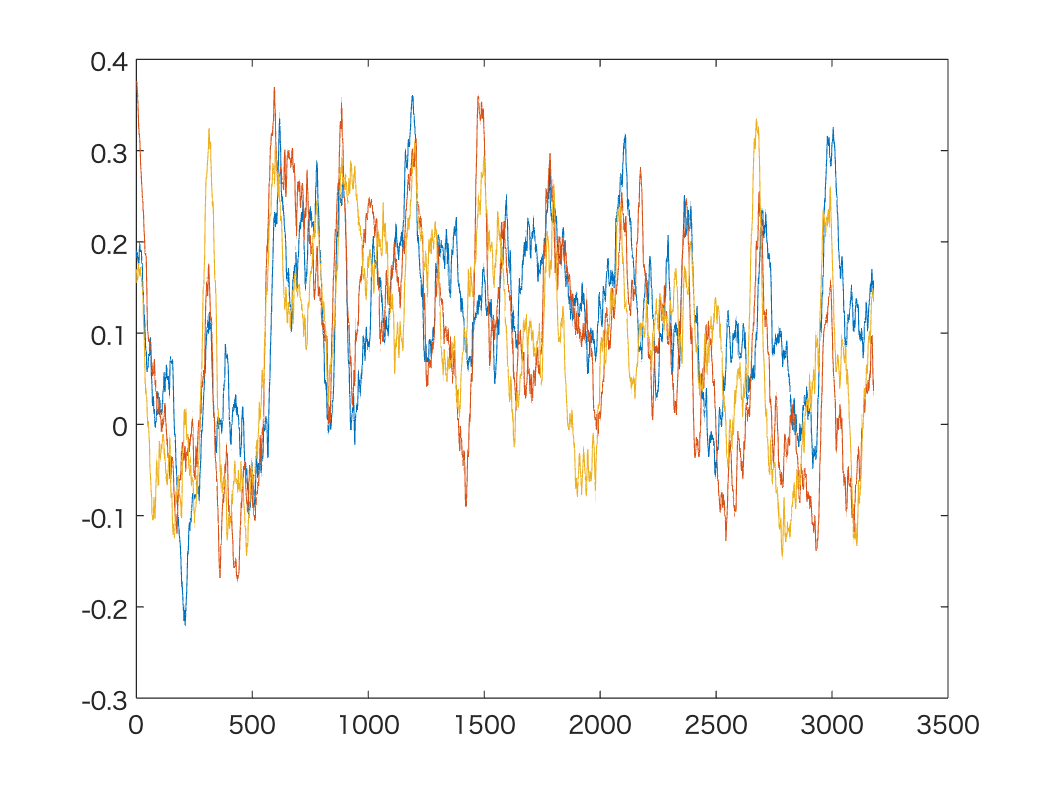

active_phi = zeros(18, time);
passive_phi = zeros(18, time);
control_phi = zeros(18, time);

for ind = 1 :18
    active_phi(ind, :) = movmean(active_MIP_PHI(ind, :), 50);
    passive_phi(ind, :) = movmean(passive_MIP_PHI(ind, :), 50);
    control_phi(ind, :) = movmean(control_MIP_PHI(ind, :), 50);
end

% Blue-Moderate: Red-Difficult: Yellow-Easy
plot(mean(active_phi))
hold on
plot(mean(passive_phi))
plot(mean(control_phi))
hold off


result = [mean(active_phi);mean(passive_phi);mean(control_phi)].';
%writematrix(result, "SF_MIP_series_" + num2str(interval) + ".csv");


Figure 2 B

% set index = 2 in MIP_import
MIP_import

MIP_type = unique([unique_without_nan(active_MIP); ...
    unique_without_nan(passive_MIP); unique_without_nan(control_MIP)]);

MIP_frequency_Prev = zeros(3, size(MIP_type, 1), 18);
MIP_frequency_Stim = zeros(3, size(MIP_type, 1), 18);
MIP_frequency_Post = zeros(3, size(MIP_type, 1), 18);

t1 = times(2);  t2= times(3); t_end=times(1);
t1_interval = 1:t1; t2_interval = t1:t2; t3_interval = t2:t_end;

T1 = length(t1_interval);
T2 = length(t2_interval);
T3 = length(t3_interval);

for ind = 1 :18
    for i = 1 : length(MIP_type)
        MIP_frequency_Prev(1, i, ind) = sum(active_MIP(ind, t1_interval)==MIP_type(i))/T1;
        MIP_frequency_Prev(2, i, ind) = sum(passive_MIP(ind, t1_interval)==MIP_type(i))/T1;
        MIP_frequency_Prev(3, i, ind) = sum(control_MIP(ind, t1_interval)==MIP_type(i))/T1;
    
        MIP_frequency_Stim(1, i, ind) = sum(active_MIP(ind, t2_interval)==MIP_type(i))/T2;
        MIP_frequency_Stim(2, i, ind) = sum(passive_MIP(ind, t2_interval)==MIP_type(i))/T2;
        MIP_frequency_Stim(3, i, ind) = sum(control_MIP(ind, t2_interval)==MIP_type(i))/T2;
    
        MIP_frequency_Post(1, i, ind) = sum(active_MIP(ind, t3_interval)==MIP_type(i))/T3;
        MIP_frequency_Post(2, i, ind) = sum(passive_MIP(ind, t3_interval)==MIP_type(i))/T3;
        MIP_frequency_Post(3, i, ind) = sum(control_MIP(ind, t3_interval)==MIP_type(i))/T3;
    end
end

mean_stim_bar = zeros(length(MIP_type), 3);
MIP_list = [];

for j = 1 : length(MIP_type)
    count = [0, 0, 0];
    for i = 1 : 3
        A = reshape(MIP_frequency_Stim(i, j, :) - MIP_frequency_Prev(i, j, :), [18, 1]);
        [s, p] = ttest(A, zeros(18,1));
        mean_stim_bar(j, i) = mean(A);
        if p < 0.05
            count(i) = 1;
        end
    end
    if sum(count) >= 1
         MIP_list = [MIP_list, j];
         bit_seq_rev(MIP_type(j))
        count
    end
end

ans = "Cz"

count =      1     0     0


ans = "Pz"

count =      0     1     0


ans = "ECG"

count =      1     1     1


ans = "EDA"

count =      1     1     1


ans = 1×2 の string 配列
    "Pz"    "EDA"


count =      1     0     0


ans = 1×2 の string 配列
    "ECG"    "EDA"


count =      0     0     1


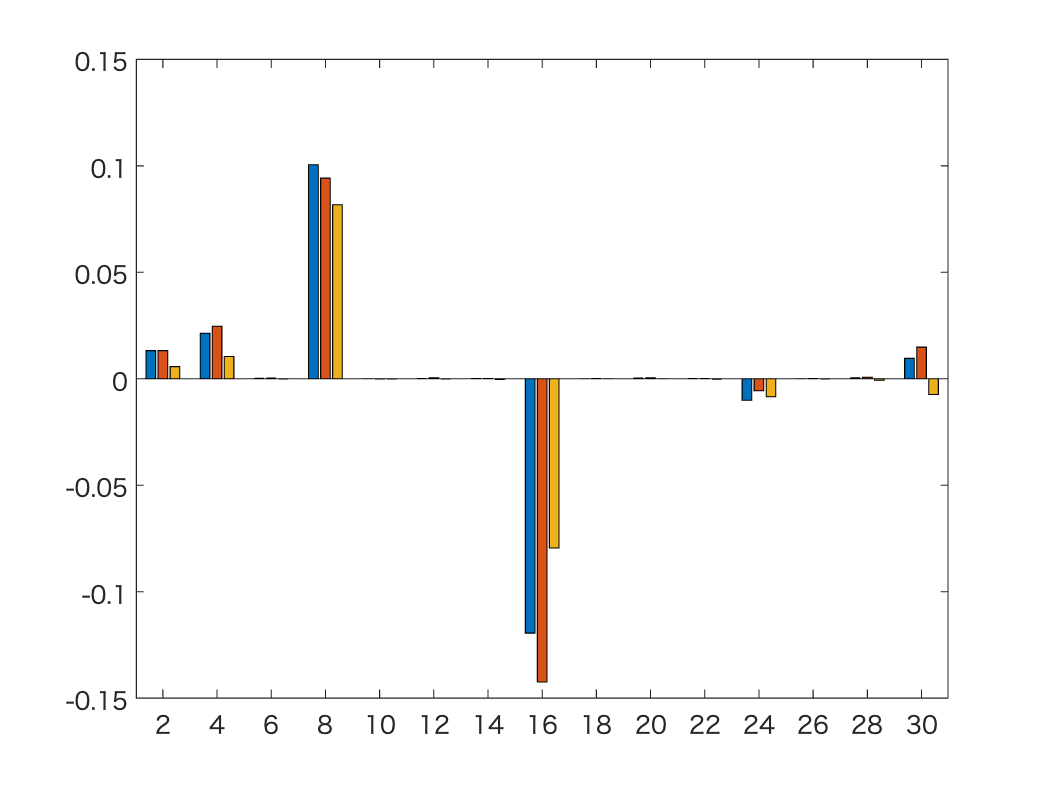


% Blue-Moderate: Red-Difficult: Yellow-Easy
% We pick up P <.05.
bar(MIP_type , mean_stim_bar)

Figure 2 - Table 1 : Each MIP-cut difference

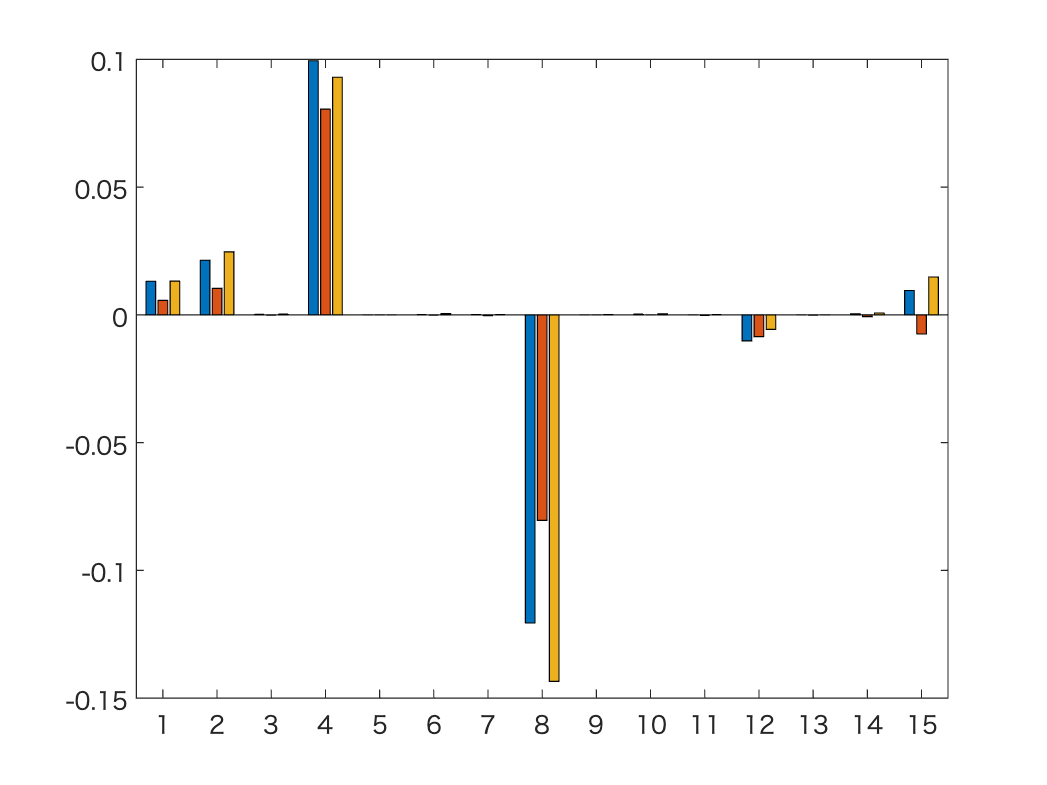

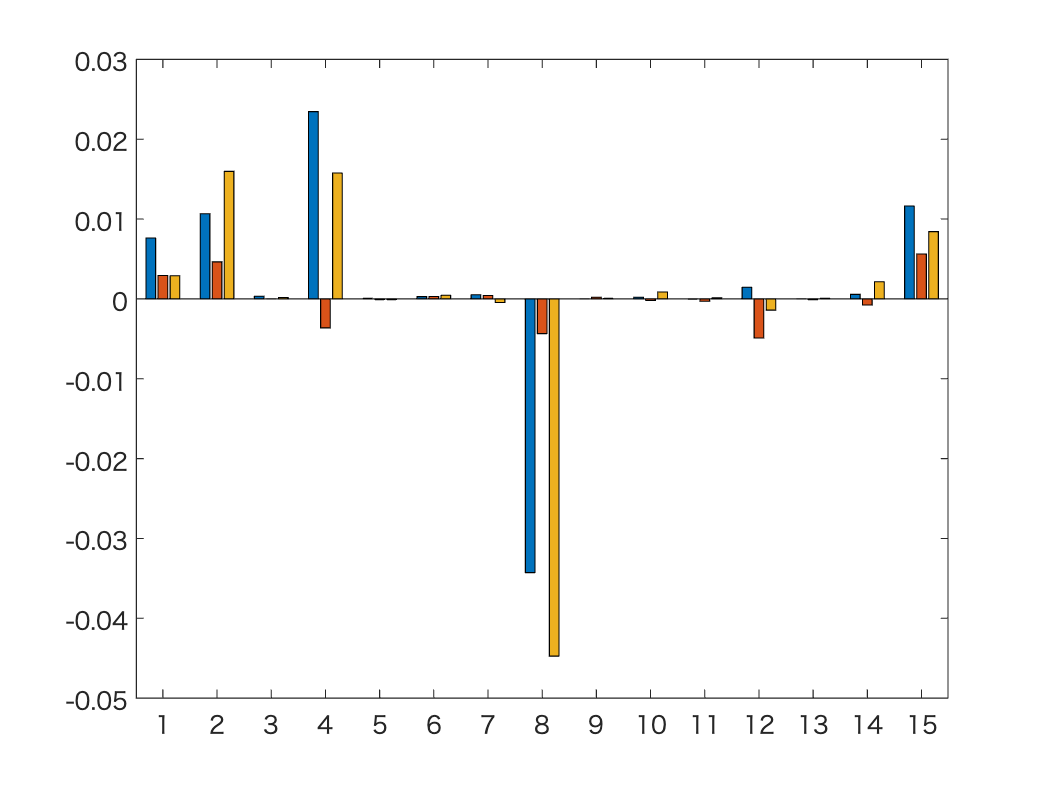

ans = 1×2 の string 配列
    "2"    "Cz"


ans = 1×2 の string 配列
    "4"    "Pz"


ans = 1×3 の string 配列
    "6"    "Cz"    "Pz"


ans = 1×2 の string 配列
    "8"    "ECG"


ans = 1×3 の string 配列
    "10"    "Cz"    "ECG"


ans = 1×3 の string 配列
    "12"    "Pz"    "ECG"


ans = 1×4 の string 配列
    "14"    "Cz"    "Pz"    "ECG"


ans = 1×2 の string 配列
    "16"    "EDA"


ans = 1×3 の string 配列
    "18"    "Cz"    "EDA"


ans = 1×3 の string 配列
    "20"    "Pz"    "EDA"


ans = 1×4 の string 配列
    "22"    "Cz"    "Pz"    "EDA"


ans = 1×3 の string 配列
    "24"    "ECG"    "EDA"


ans = 1×4 の string 配列
    "26"    "Cz"    "ECG"    "EDA"


ans = 1×4 の string 配列
    "28"    "Pz"    "ECG"    "EDA"


ans = 1×5 の string 配列
    "30"    "Cz"    "Pz"    "ECG"    "EDA"


cp1 = cut_point(4);

bit_seq_rev(cp1)

ans = "ECG"

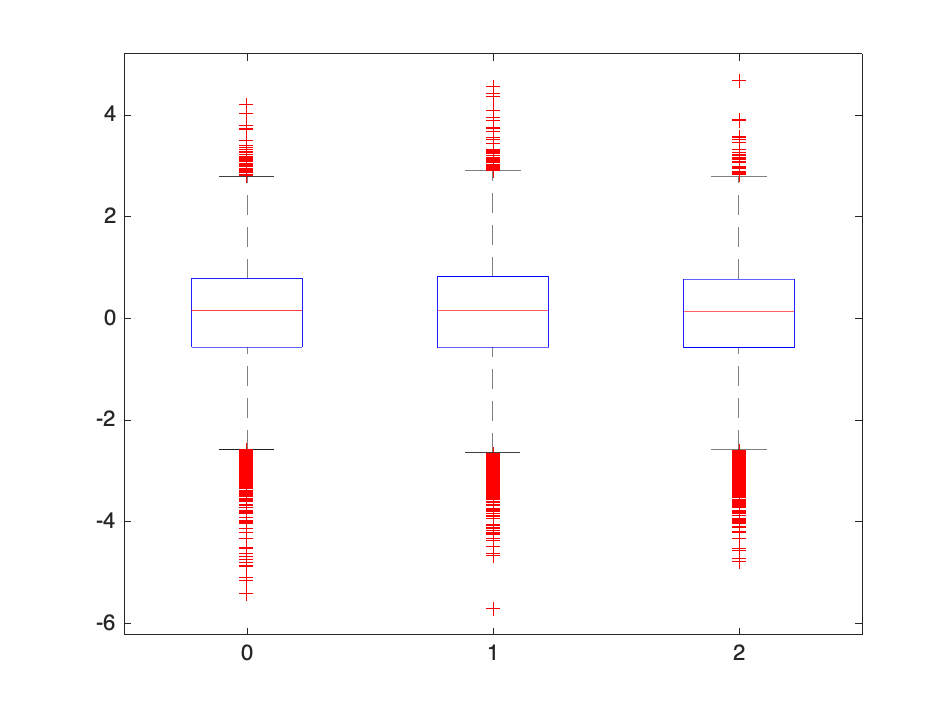


mip_active_bf = active_mip_bf(find(active_bf==cp1));
mip_passive_bf = passive_mip_bf(find(passive_bf==cp1));
mip_control_bf = control_mip_bf(find(control_bf==cp1));

mip_active_task = active_mip_task(find(active_task==cp1));
mip_passive_task = passive_mip_task(find(passive_task==cp1));
mip_control_task = control_mip_task(find(control_task==cp1));

mip_active_af = active_mip_af(find(active_af==cp1));
mip_passive_af = passive_mip_af(find(passive_af==cp1));
mip_control_af = control_mip_af(find(control_af==cp1));

x1 = (mip_active_task-mean(mip_active_bf)).';
x2 = (mip_passive_task-mean(mip_passive_bf)).';
x3 = (mip_control_task-mean(mip_control_bf)).';
x = [x1; x2; x3];
g = [zeros(length(x1), 1); ones(length(x2), 1); 2*ones(length(x3), 1)];
boxplot(x, g)


[mean(x1), mean(x2), mean(x3)]

ans =     0.0743    0.0970    0.0702


[std(x1), std(x2), std(x3)]

ans =     1.0318    1.0714    1.0340


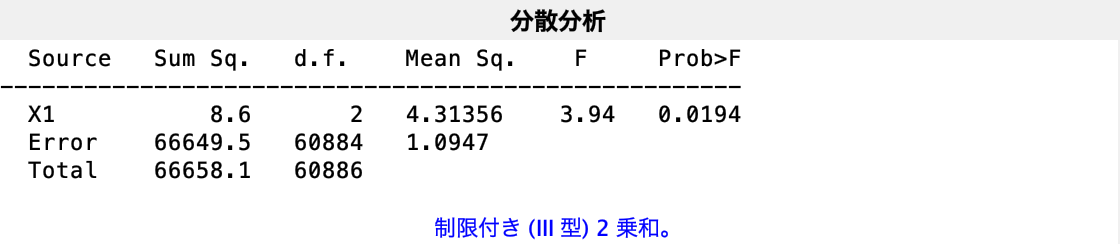


[p,tbl,stats] = anovan(x, g);

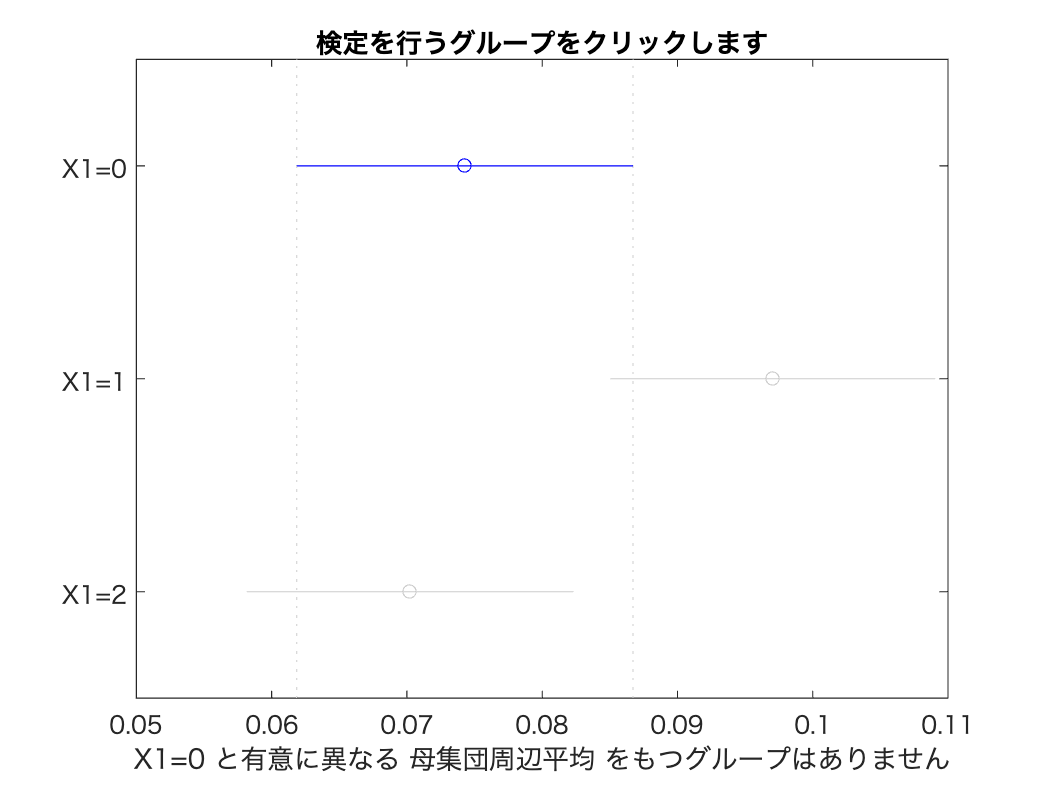

c =     1.0000    2.0000   -0.0472   -0.0228    0.0017    0.0742
    1.0000    3.0000   -0.0205    0.0041    0.0286    0.9203
    2.0000    3.0000    0.0027    0.0268    0.0509    0.0247


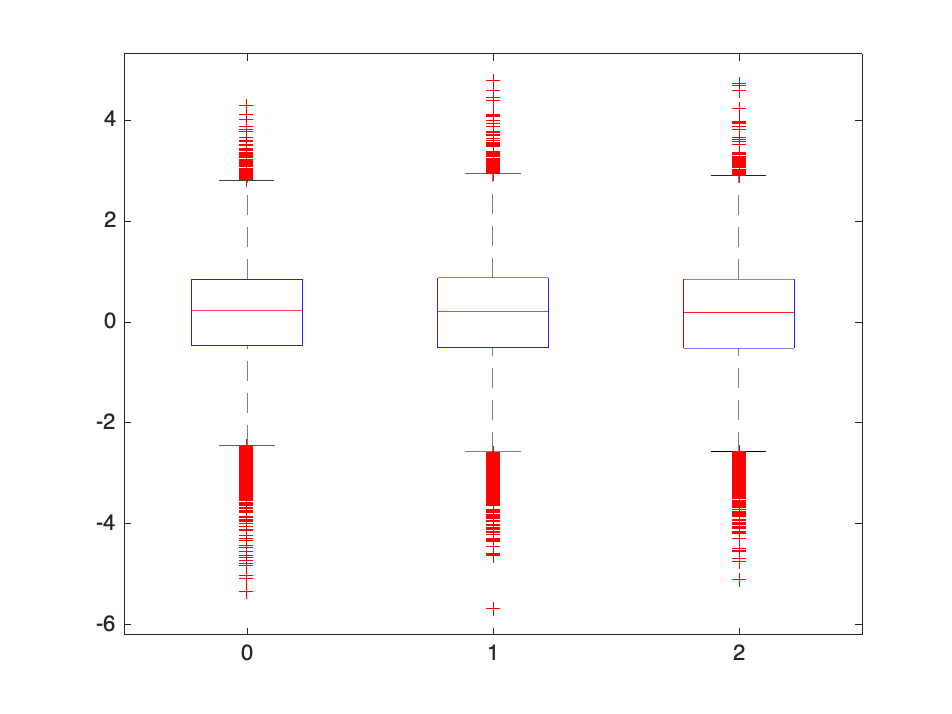

ans =     0.1551    0.1551    0.1362


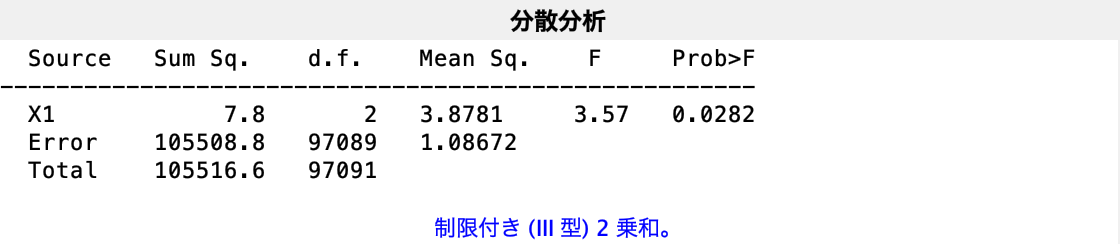

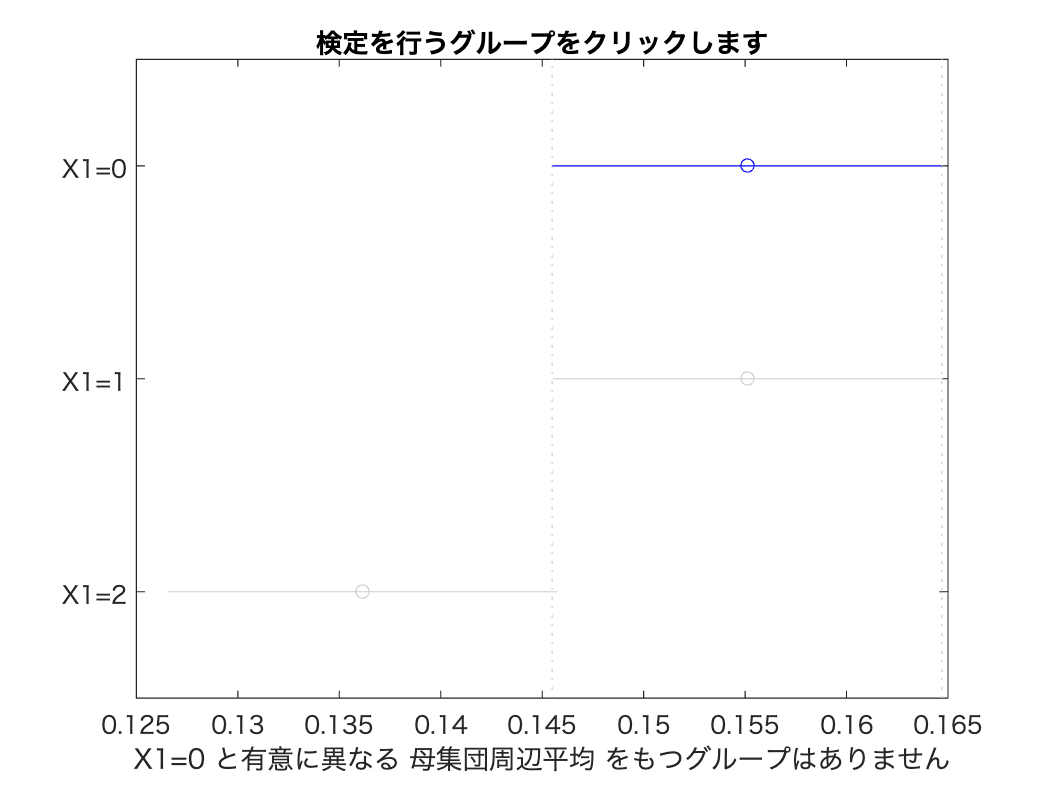

c =     1.0000    2.0000   -0.0192   -0.0000    0.0192    1.0000
    1.0000    3.0000   -0.0003    0.0189    0.0382    0.0542
    2.0000    3.0000   -0.0002    0.0190    0.0382    0.0537


c = multcompare(stats)